## **Przetwarzanie Sygnałów Cyfrowych**

# Analiza harmoniczna cz. 2

## Jan Rosa 410269 AiR

## Kod i dane z poprzedniech zadań

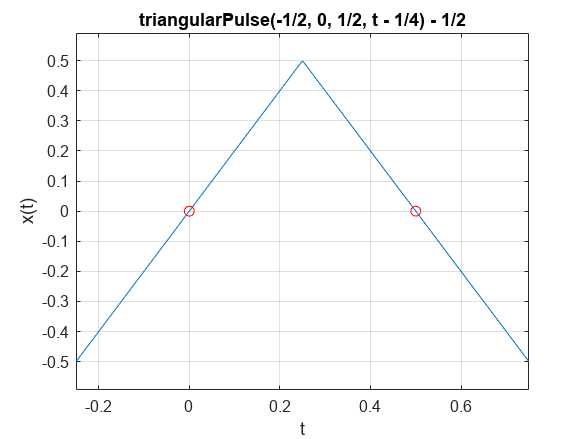

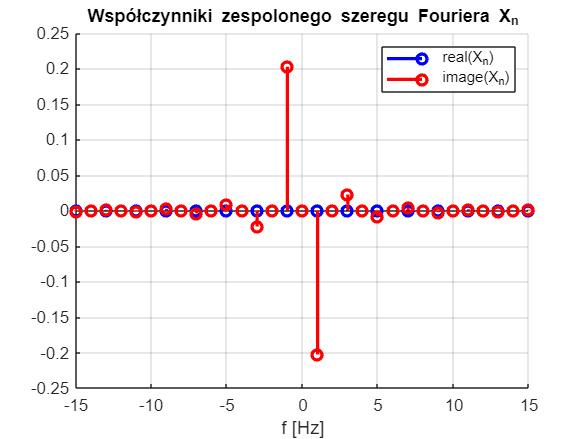


bsd =

     []



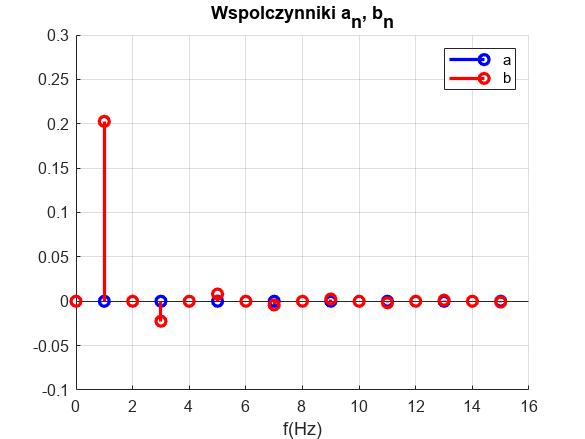

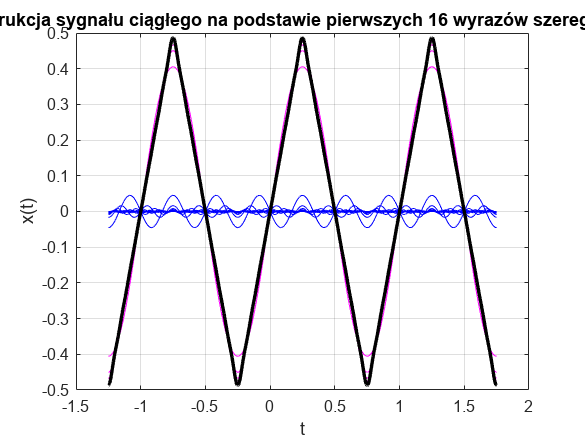

$$func = \mathrm{rectangularPulse}\left(0,1,x\right)-\frac{1}{2}$$

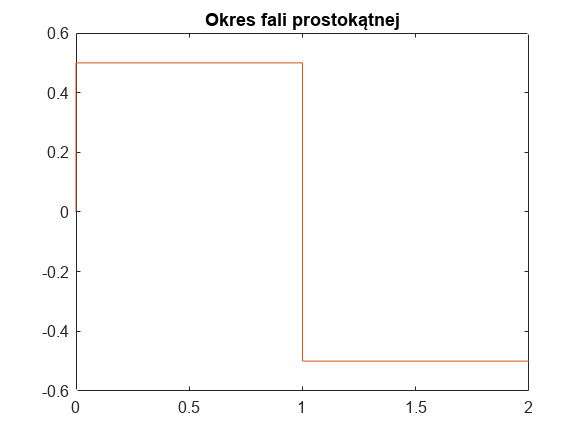

ww0 = 3.1416

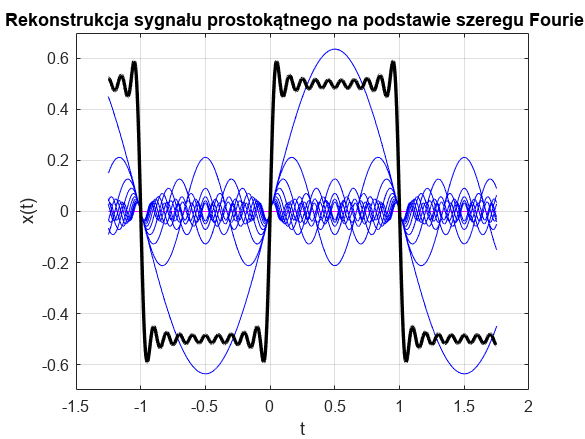

THD = 0.4569

Lab_3

###  Zadanie 5 

Wykorzystuj¡c wcze±niejsze programy, wykonaj rekonstrukcj¦ 3-ch okresów przebiegu wej±ciowego na podstawie elementów szeregu zespolonego. Porównaj rezultaty rekonstrukcji z tymi uzyskanymi w w. 4 oraz z ci¡gªym przebiegiem widocznym na rysunku 1. Wylicz bª¡d aproksymacji przebiegu. W sprawozdaniu zanotuj warto±¢ bª¦du oraz umie±¢ kod programu. Opisz jaki wpªyw na rekonstrukcj¦ sygnaªu ma ogranicznie liczby elementów szeregu.

NTS = 31;
time1 = -1.25:0.01:1.75;
w01 = 2 * pi;
signal = zeros(size(time1));
signalt = []


signalt =

     []



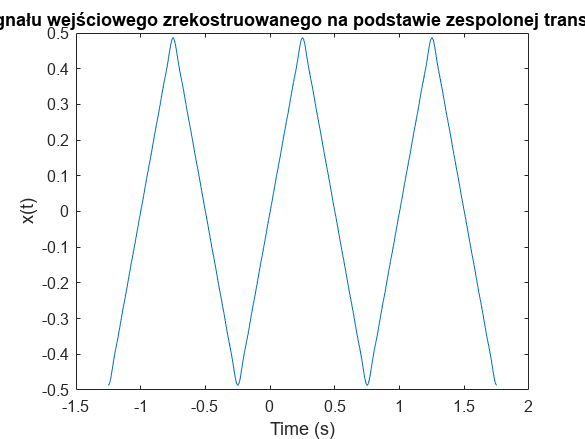

for n1 = 1:NTS
    signal = signal + X(n1)*exp(1i*(n1-16)*w01*time1);
end 
figure
plot(time1, real(signal))
xlabel("Time (s)")
ylabel("x(t)")
title("trzy okresy sygnału wejściowego zrekostruowanego na podstawie zespolonej transformaty Fouriera")

Błąd aproksymacji przebiegu wyliczony za pomocą obliczenia warości skutecznych dal każdego z sygnalów:

Wartość skuteczna orginału:

syms time
x1 = triangularPulse(t1,0,t2,time-offset)-0.5;
P1 = ((1)* (int((x1)^2, time, -0.25, 0.75)));
P1= double(P1)

P1 = 0.0833

Wartość skuteczna rekostrukcji:

krok = size(signal);
krok = 3/krok(2);
psignal = real(signal(1:101)).^2;
P2 = (sum(psignal)*krok)

P2 = 0.0854

Błąd bezwzględny przybliżenia:

abserror = abs(P1 - P2)

abserror = 0.0021

Błąd względny przybliżenia:

relerror = abserror/P1

relerror = 0.0250

Błędy aproksymacji przebiegu są niewielkie, ograniczenie liczby elementów przebiegu zmniejsza dokładność odwzorowania sygnału wejściowego

### Zadanie 6 

Wykonaj poni»sze obliczenia a wyniki zanotuj w sprawozdaniu. 

a) Wylicz metod¡ symboliczn¡ wspóªczynnik warto±ci skutecznej dla przebiegu sinusoidalnego. Wynik zamień na posta¢ numeryczn¡ i przypisz do zmiennej skd. Zweryfikuj rezultat z obliczeniami analitycznymi ("na papierze") lub z tablicami. Podaj wzór na wspóªczynnik sk i sprawd¹ poprawno±¢ wyliczenia skd. 

b) Wylicz warto±¢ skuteczn¡ sygnaªu ci¡gªego x(t) zde�niowanego w Ćw. 1. 

c) Wylicz warto±¢ skuteczn¡ sygaªu ci¡gªego zrekonstruowanego na podstawie 16-tu funkcji bazowych z Ćw. 4.

a)

syms time
%sin ma jedną skałdową harmoczniczną
S1 = sqrt((1/(2*pi))* (int(sin(time)^2,time, 0, 2*pi)))

$$S1 = \frac{\sqrt{5734161139222659}\,\sqrt{36028797018963968}\,\sqrt{\pi }}{36028797018963968}$$

S1= double(S1)

S1 = 0.7071

S1 równe $\frac{\sqrt{2}}{2}\approx 0\ldotp 7071$co est wartością tablicową

b)

x1 = triangularPulse(t1,0,t2,time-offset)-0.5;
S2 = sqrt((1)* (int((x1)^2, time, -0.25, 0.75)))

$$S2 = \frac{\sqrt{3}}{6}$$

S2= double(S2)

S2 = 0.2887

wartość skuteczna sygału trókątnego to $\frac{\sqrt{3}}{6}\approx 0\ldotp 2887$ 

c)

krok = size(xx);
krok = 3/krok(2);
pxx = (xx(1:1001)).^2;
%plot(pxx)
S3 = sqrt(sum(pxx)*krok)

S3 = 0.2890

Wartość skuteczna sygnału zrekostruowanego w ćw. 4 to 0.2890 co jest wartością bliską wartości skutecznej oryginału

### Zadanie 7

 Stosuj¡c obliczenia symboliczne wyznacz numeryczną warto±¢ wspóªczynnika znieksztaªce« harmonicznych THD sygnaªu dla liczby wspóªczynników n ∈ {5, 10, 15}. Kod programu oraz wyniki wraz z wnioskami umie±¢ w sprawozdaniu. Znajd¹ w literaturze analityczn¡ formuª¦ na warto±¢ skuteczn¡ oraz wspóªczynnik THD przebiegu i oceń dokładność

syms t

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice ca³kowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;
NT = 0:15;
a=[];
b=[];
for n = NT
 a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
 b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

Dla n=5

s = 0;
for n = 2:5
    s = s + (abs(1j*b(n+1)).^2)/2;
end
thd5 = sqrt(s)/(abs(a(2) + 1j*b(2))/sqrt(2));
thd5

thd5 = 0.1181

Dla n=10

s = 0;
for n = 2:10
    s = s + (abs(1j*b(n+1)).^2)/2;
end
thd10 = sqrt(s)/(abs(a(2) + 1j*b(2))/sqrt(2));
thd10

thd10 = 0.1205

Dla n =15

s = 0;
for n = 2:15
    s = s + (abs(1j*b(n+1)).^2)/2;
end
thd15 = sqrt(s)/(abs(a(2) + 1j*b(2))/sqrt(2));
thd15

thd15 = 0.1210

### Zadanie domowe - wyjście falownika

Powtórz ¢wiczenia i zadania 1-7 dla przebiegu P3. Umie±¢ w sprawozdaniu przebieg jednego okresu sygnaªu ci¡gªego, wykres wspóªczynników, warto±¢ skuteczn¡, wynik aproksymacji za pomoc¡ 16-tu funkcji bazowych na wykresie oraz wspóªczynnik zawarto±ci harmonicznych THD. 

Skonstruowanie jednego okresu sygnału

syms time
Ts0 = [-1.5, 4.5];
T0S = 6;
w0s = 2/T0S*pi;
xTT = sym(-1.5);
xTT = xTT + rectangularPulse(-1, 4, time) + rectangularPulse(0, 3, time) + rectangularPulse(1, 2, time)

$$xTT = \mathrm{rectangularPulse}\left(0,3,\text{time}\right)+\mathrm{rectangularPulse}\left(1,2,\text{time}\right)+\mathrm{rectangularPulse}\left(-1,4,\text{time}\right)-\frac{3}{2}$$

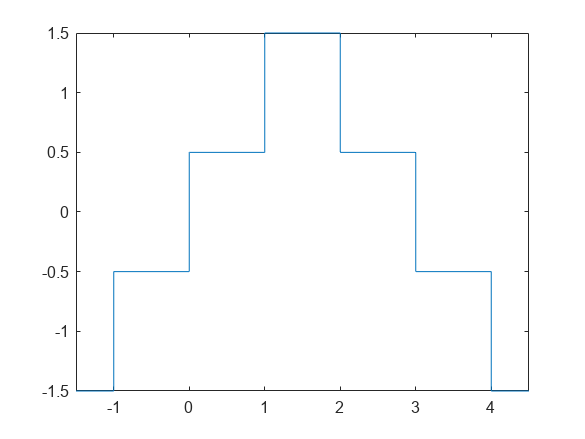

fplot(xTT, Ts0)

Wyznaczenie wspołczynników zespolonego szeregu Fouriera 

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0S)*int(xTT*exp(-1i*w0s*n*time),time,Ts0);
    %Xn to współczynnik
    X(n + NT + 1) = Xn;
end

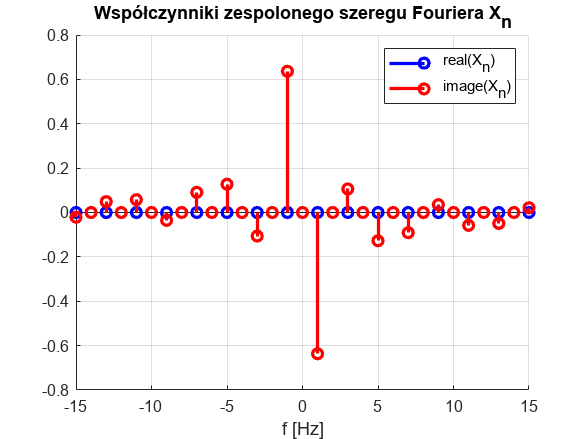

figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')
hold off

wyznaczenie trygonometrycznych współczynników szerego Fouriera

NT = 0:15;
a=[];
b=[];
for n = NT
 a(n+1) = (1/T0S)*int(xTT*cos(w0s*n*time),time,Ts0);
 b(n+1) = (1/T0S)*int(xTT*sin(w0s*n*time),time,Ts0);
end
a;
b;

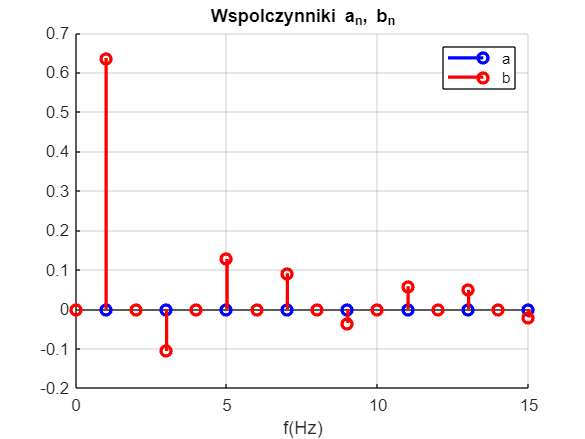

figure();
hold on,
grid on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
title('Wspolczynniki a_n, b_n')
xlabel("f(Hz)")
legend('a','b')
hold off

Rekonstrukcja sygnału na podstawie trygonometrycznego szeregu fouriera

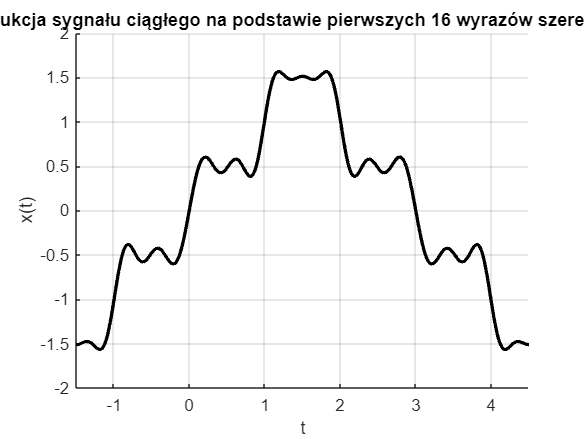

step = (Ts0(2) - Ts0(1))/1000;
tt = Ts0(1)-T0 : step: Ts0(2) + T0;
xx = zeros(1,length(tt));
xx = xx + a(1); % skladowa stala
figure
grid on; 
hold on;
xlabel('t'); 
ylabel('x(t)');
for n = NT
 xx_n = 2*(a(n+1)*cos(w0s*n*tt) + b(n+1)*sin(w0s*n*tt));
 xx = xx + xx_n;
 title(sprintf('n = %d',n+1)); 
 %pause(0.1);
 end
plot(tt,xx,'k','LineWidth',2);
title('Rekonstrukcja sygnału ciągłego na podstawie pierwszych 16 wyrazów szeregu Fouriera')
xlim([-1.5, 4.5])
hold off

Rekonstrukcja sygnału na podstawie zespolonego szeregu fouriera

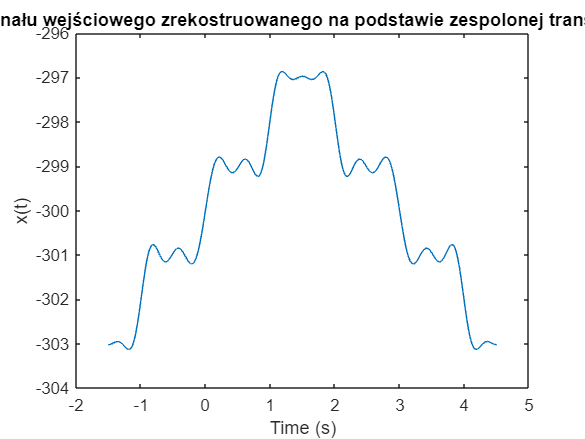

NTS = 31;
time1 = Ts0(1):0.01:Ts0(2);
signal = zeros(size(time1))-300;
for n1 = 1:NTS
    signal = signal + 2*X(n1)*exp(1i*(n1-16)*w0s*time1);
end 
figure
plot(time1, real(signal))
xlabel("Time (s)")
ylabel("x(t)")
title("trzy okresy sygnału wejściowego zrekostruowanego na podstawie zespolonej transformaty Fouriera")

Wartość skuteczna

S4 = sqrt((1/T0S)* (int((xTT)^2, time, Ts0(1), Ts0(2))))

$$S4 = \frac{\sqrt{3}\,\sqrt{11}}{6}$$

S4= double(S4)

S4 = 0.9574

THD

s = 0;
for n = 2:15
    s = s + (abs(a(n+1) + 1j*b(n+1))^2)/2;
end
div = (abs(a(2) + 1j*b(2)))/sqrt(2);
thdtt = sqrt(s)/div

thdtt = 0.3264

### Zadanie domowe - fala zadana

Powtórz ¢wiczenia i zadania 1-7 dla przebiegu P3. Umie±¢ w sprawozdaniu przebieg jednego okresu sygnaªu ci¡gªego, wykres wspóªczynników, warto±¢ skuteczn¡, wynik aproksymacji za pomoc¡ 16-tu funkcji bazowych na wykresie oraz wspóªczynnik zawarto±ci harmonicznych THD. 

Skonstruowanie jednego okresu sygnału

syms time
Ts0 = [0, 0.01];
T0S = 0.01;
w0s = 2/T0S*pi;
xTT = abs(325*sin(50*2*pi*time))

$$xTT = 325\,\left|\sin\left(100\,\pi \,\text{time}\right)\right|$$

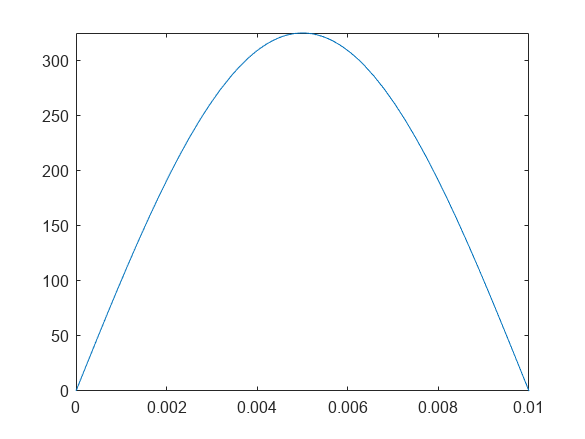

fplot(xTT,Ts0)

Wyznaczenie wspołczynników zespolonego szeregu Fouriera 

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0S)*int(xTT*exp(-1i*w0s*n*time),time,Ts0);
    %Xn to współczynnik
    X(n + NT + 1) = Xn;
end

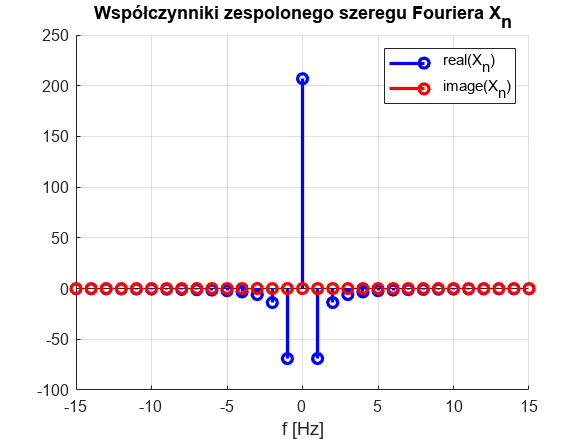

figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')
hold off

wyznaczenie trygonometrycznych współczynników szerego Fouriera

NT = 0:15;
a=[];
b=[];
for n = NT
 a(n+1) = (1/T0S)*int(xTT*cos(w0s*n*time),time,Ts0);
 b(n+1) = (1/T0S)*int(xTT*sin(w0s*n*time),time,Ts0);
end
a;
b;

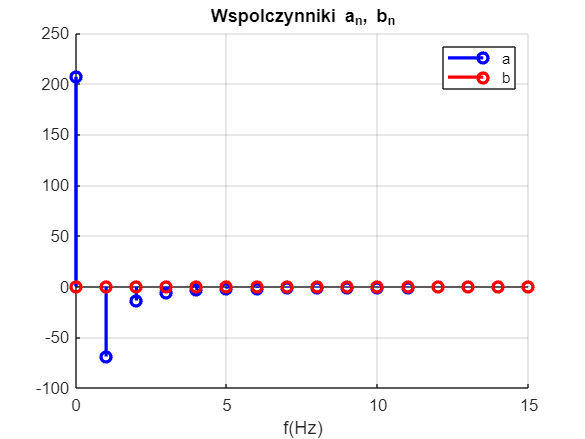

figure();
hold on,
grid on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
title('Wspolczynniki a_n, b_n')
xlabel("f(Hz)")
legend('a','b')
hold off

Rekonstrukcja sygnału na podstawie trygonometrycznego szeregu fouriera

tt = linspace(Ts0(1),Ts0(2),1000);
xx = zeros(1,length(tt));
xx = xx + a(1)

xx =   206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014  206.9014


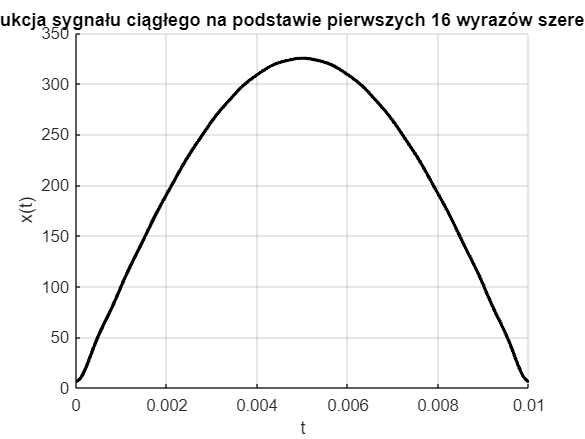

figure
grid on; 
hold on;
xlabel('t'); 
ylabel('x(t)');
for n = 1:15
 xx_n = 2*(a(n+1)*cos(w0s*n*tt) + b(n+1)*sin(w0s*n*tt));
 %plot(tt,xx_n, 'LineWidth',1)
 xx = xx + xx_n;
 end
plot(tt,xx,'k','LineWidth',2);
title('Rekonstrukcja sygnału ciągłego na podstawie pierwszych 16 wyrazów szeregu Fouriera')
xlim(Ts0)
hold off

Rekonstrukcja sygnału na podstawie zespolonego szeregu fouriera

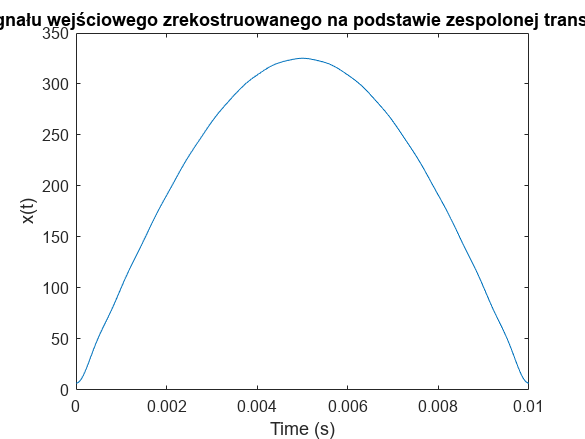

NTS = 31;
time1 = linspace(Ts0(1),Ts0(2), 1000);
signal = zeros(size(time1));
for n1 = 1:NTS
    ex = X(n1)*exp(1i*(n1-16)*w0s*time1);
    signal = signal + ex;
end 
figure
plot(time1, abs(signal))
xlabel("Time (s)")
ylabel("x(t)")
title("trzy okresy sygnału wejściowego zrekostruowanego na podstawie zespolonej transformaty Fouriera")

Wartość skuteczna

S4 = sqrt((1/T0S)* (int((xTT)^2, time, Ts0(1), Ts0(2))))

$$S4 = \frac{325\,\sqrt{2}}{2}$$

S4= double(S4)

S4 = 229.8097

THD

s = 0;
for n = 2:15
    s = s + (abs(a(n+1) + 1j*b(n+1))^2)/2;
end
div = (abs(a(2) + 1j*b(2)))/sqrt(2);
thdtt = sqrt(s)/div

thdtt = 0.2272

### Zadanie domowe - fala prostokątna

Powtórz ¢wiczenia i zadania 1-7 dla przebiegu P3. Umie±¢ w sprawozdaniu przebieg jednego okresu sygnaªu ci¡gªego, wykres wspóªczynników, warto±¢ skuteczn¡, wynik aproksymacji za pomoc¡ 16-tu funkcji bazowych na wykresie oraz wspóªczynnik zawarto±ci harmonicznych THD. 

Skonstruowanie jednego okresu sygnału

syms time
Ts0 = [0, 2];
T0S = 2;
w0s = 2/T0S*pi;
xTT = rectangularPulse(0, 1, time)

$$xTT = \mathrm{rectangularPulse}\left(0,1,\text{time}\right)$$

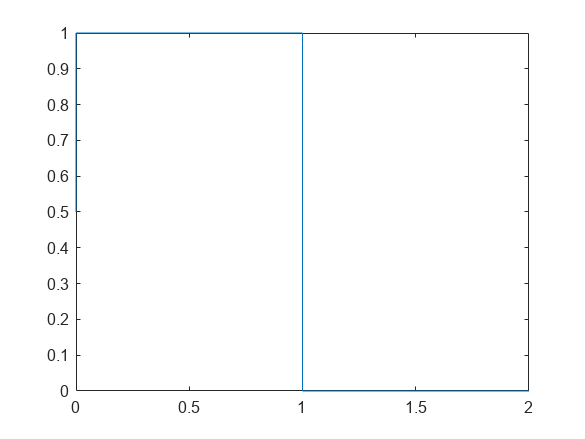

fplot(xTT, Ts0)

Wyznaczenie wspołczynników zespolonego szeregu Fouriera 

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0S)*int(xTT*exp(-1i*w0s*n*time),time,Ts0);
    %Xn to współczynnik
    X(n + NT + 1) = Xn;
end

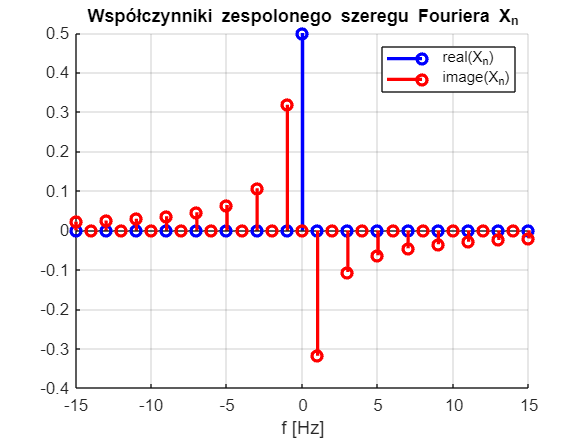

figure; hold on; 
stem(ind*f0,real(X),'b','LineWidth',2); 
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2); 
grid on
legend('real(X_n)','image(X_n)','Location','NorthEast')
title('Współczynniki zespolonego szeregu Fouriera X_n')
hold off

wyznaczenie trygonometrycznych współczynników szerego Fouriera

NT = 0:15;
a=[];
b=[];
for n = NT
 a(n+1) = (1/T0S)*int(xTT*cos(w0s*n*time),time,Ts0);
 b(n+1) = (1/T0S)*int(xTT*sin(w0s*n*time),time,Ts0);
end
a;
b;

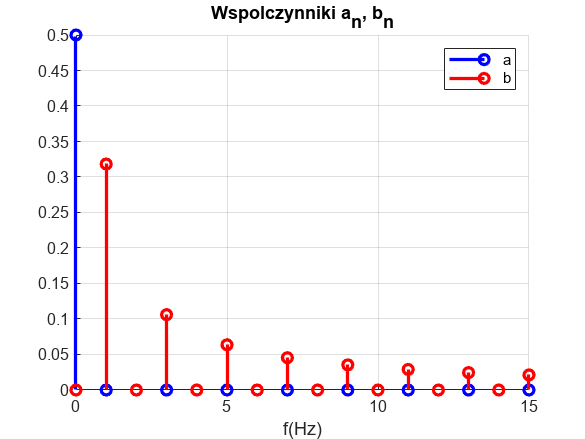

figure();
hold on,
grid on
stem(NT,a,'b','LineWidth',2);
xlabel('n')
stem(NT,b,'r','LineWidth',2);
title('Wspolczynniki a_n, b_n')
xlabel("f(Hz)")
legend('a','b')
hold off

Rekonstrukcja sygnału na podstawie trygonometrycznego szeregu fouriera

tt = linspace(Ts0(1),Ts0(2),1000);
xx = zeros(1,length(tt));
xx = xx + a(1)

xx =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000


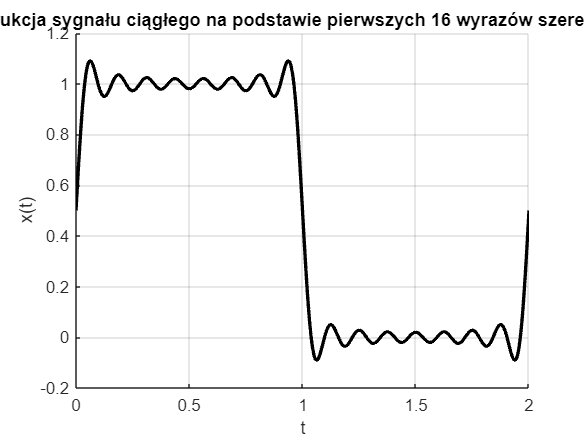

figure
grid on; 
hold on;
xlabel('t'); 
ylabel('x(t)');
for n = 1:15
 xx_n = 2*(a(n+1)*cos(w0s*n*tt) + b(n+1)*sin(w0s*n*tt));
 %plot(tt,xx_n, 'LineWidth',1)
 xx = xx + xx_n;
 end
plot(tt,xx,'k','LineWidth',2);
title('Rekonstrukcja sygnału ciągłego na podstawie pierwszych 16 wyrazów szeregu Fouriera')
xlim(Ts0)
hold off

Rekonstrukcja sygnału na podstawie zespolonego szeregu fouriera

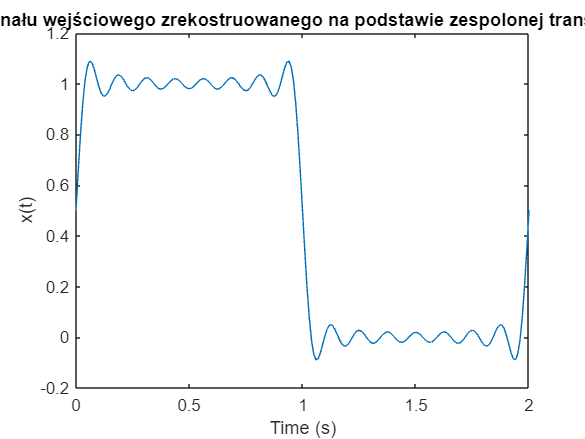

NTS = 31;
time1 = Ts0(1):0.01:Ts0(2);
signal = zeros(size(time1));
for n1 = 1:NTS
    signal = signal + X(n1)*exp(1i*(n1-16)*w0s*time1);
end 
figure
plot(time1, real(signal))
xlim(Ts0)
xlabel("Time (s)")
ylabel("x(t)")
title("trzy okresy sygnału wejściowego zrekostruowanego na podstawie zespolonej transformaty Fouriera")

Wartość skuteczna

S4 = sqrt((1/T0S)* (int((xTT)^2, time, Ts0(1), Ts0(2))))

$$S4 = \frac{\sqrt{2}}{2}$$

S4= double(S4)

S4 = 0.7071

THD

s = 0;
for n = 2:15
    s = s + (abs(a(n+1) + 1j*b(n+1))^2)/2;
end
div = (abs(a(2) + 1j*b(2)))/sqrt(2);
thdtt = sqrt(s)/div

thdtt = 0.4500